clear


startX = -4;
endX = 4;


maxDevsX = [];
maxDevsY = [];


alphasX = [];
alphasY = [];


h = 0.01;
endH = 0.00001;

while h > endH
   
    maxDev = 0;

    for j = 1:floor((endX - startX)/h)
        x = startX + (j-1)*h;
        curDev = abs(II2(x, h) - df(x));
        if curDev > maxDev
            maxDev = curDev;
        end
    end

    maxDevsX = [maxDevsX, h];
    maxDevsY = [maxDevsY, maxDev];

    curAlpha = log(maxDev)/log(h);
    alphasX = [alphasX, h];
    alphasY = [alphasY, curAlpha];

    h = h * 0.5;
end


alphasX

alphasX =     0.0100    0.0050    0.0025    0.0013    0.0006    0.0003    0.0002    0.0001    0.0000    0.0000


alphasY

alphasY =     2.3891    2.3382    2.2991    2.2680    2.2429    2.2220    2.2044    2.1894    2.1762    2.1637




CX = [];
CY = [];


presumedAlpha = 2;

h = 0.01;
endH = 0.00001;

curMaxDevI = 1;

while h > endH

    maxDev = maxDevsY(curMaxDevI);

    CX = [CX, h];
    CY = [CY, maxDev/h^presumedAlpha];
maxDev
maxDev/h^presumedAlpha
    h = h * 0.5;
    curMaxDevI = curMaxDevI + 1;
end

maxDev = 1.6667e-05

ans = 0.1667

maxDev = 4.1667e-06

ans = 0.1667

maxDev = 1.0417e-06

ans = 0.1667

maxDev = 2.6042e-07

ans = 0.1667

maxDev = 6.5104e-08

ans = 0.1667

maxDev = 1.6276e-08

ans = 0.1667

maxDev = 4.0699e-09

ans = 0.1667

maxDev = 1.0182e-09

ans = 0.1668

maxDev = 2.5523e-10

ans = 0.1673

maxDev = 6.4677e-11

ans = 0.1695

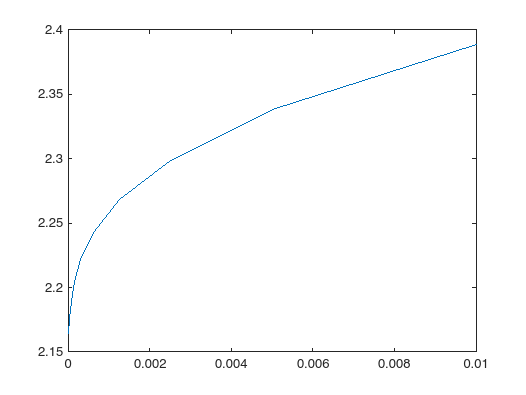



plot(alphasX, alphasY)



CX

CX =     0.0100    0.0050    0.0025    0.0013    0.0006    0.0003    0.0002    0.0001    0.0000    0.0000


CY

CY =     0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1668    0.1673    0.1695


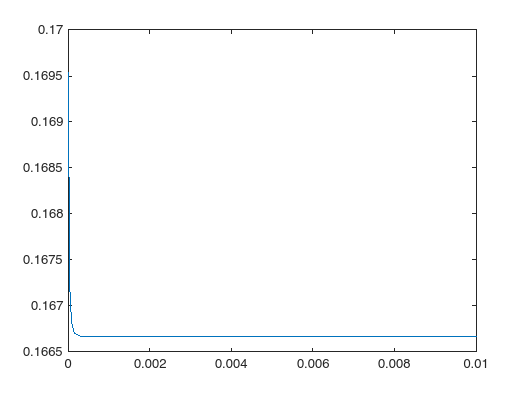


figure
plot(CX, CY)

function f = f(X)
    f = sin(X);
end

function df = df(X)
    df = cos(X);
end


function I1 = I1(x, h)
    I1 = (f(x+h) - f(x))/h;
end

function I2 = I2(x, h)
    I2 = (f(x) - f(x-h))/h;
end


function II1 = II1(x, h)
    II1 = (4*f(x+h) - 3*f(x) - f(x+2*h))/(2*h);
end

function II2 = II2(x, h)
    II2 = (f(x+h) - f(x-h))/(2*h);
end


function IV2 = IV2(x, h)
    IV2 = (f(x+3*h) - 6*f(x+2*h) + 18*f(x+h) - 10*f(x) - 3*f(x-h))/(12*h);
end

function IV3 = IV3(x, h)
    IV3 = (f(x-2*h) - 8*f(x-h) + 8*f(x+h) - f(x+2*h))/(12*h);
end